# Neural network based control for nonlinear affine systems with input saturation and neural network based observer

% simulation time initialization
Ts = 0.005;
t = 0:Ts:100;

% desired trajectory
yd = [sin(0.5*t) + cos(0.25*t); 0.5*cos(0.5*t) - 0.25*sin(0.25*t)];

% model parameters
mu = 1;
x0 = [0; 0];
Ac = -eye(2);
C = [1; 0];

% auxiliary system parameters
K = -eye(2);
h = -[10; 10]; % modifica aici DACA NU MERGE!!!!
zeta0 = [0; 0];

% controller neural network parameters
input_size_cnn = 4;
hidden_layer_size_cnn = 20;
lr_c = 0.45;
gamma_c = 0.0001;

% observer parameters
A = [0 1; 0 0];
B = [0; 1];
G = [15; 15];
G = [14;49];
Lambda = 1.6;
x_hat0 = [0.5; 0.5];
Obs = [C'; C'*Ac];
Aocl = A - G*C';

% observer neural network parameters
input_size_onn = 3;
hidden_layer_size_onn = 20;
lr_o = 30;
gamma_o = 0.03;

% control signal saturation limits
input_upper_bound = 2;
input_lower_bound = -2;

% controller neural network initialization
Vc = rands(hidden_layer_size_cnn, input_size_cnn);
Wc = rands(1, hidden_layer_size_cnn);
Vo = rands(hidden_layer_size_onn, input_size_onn);
Wo = rands(1, hidden_layer_size_onn);

% model state initialization
x = zeros(2, length(t));
zeta = zeros(2, length(t));
xi_hat = zeros(2, length(t));
x(:, 1) = x0;
zeta(:, 1) = zeta0;

u = zeros(length(t), 1);
e = zeros(2, length(t));
y_e = zeros(length(t), 1);
r = zeros(length(t), 1);

x_cnn = [x(1, 1) - yd(1, 1); xi_hat(2, 1) - yd(2, 1); yd(:, 1)] - [zeta(:, 1); 0; 0];
[u(1), delta_u] = control_saturation(-Wc*tanh(Vc*x_cnn), input_lower_bound, input_upper_bound);

## Train observer neural network

% for i = 1:length(t) - 1
%     e(:, i) = x(:, i) - yd(:, i) - zeta(:, i);
%     y_e(i) = C'*x(:, i) - C'*xi_hat(:, i);
%     
%     x_onn = [xi_hat(:, i); 1];
%     
%     % backpropagation
%     dWo = (y_e(i)*C'*inv(Aocl)*B)'*tanh(Vo*x_onn)';
%     dVo = (y_e(i)*C'*inv(Aocl)*B*Wo*(eye(hidden_layer_size_onn) - diag(tanh(Vo*x_onn).^2)))'*x_onn';
% 
%     % update
%     Wo = Wo + Ts*(-lr_o*dWo - gamma_o*norm(y_e(i))*Wo);
%     Vo = Vo + Ts*(-lr_o*dVo - gamma_o*norm(y_e(i))*Vo);
%  
%     H_hat = Wo*tanh(Vo*x_onn);
%     
%     x(:, i + 1) = x(:, i)+ Ts*van_der_pol_derivatiave(x(:, i), 1, mu);
%     xi_hat(:, i + 1) = xi_hat(:, i) + Ts*observer_derivative(xi_hat(:, i), A, B, C, G, C'*x(:, i), H_hat);
% end
% 
% figure, 
% plot(t, x(1, :)); hold on;
% plot(t, xi_hat(1, :));
% 
% figure,
% plot(t, x(2, :)); hold on;
% plot(t, xi_hat(2, :));

## Control implementation

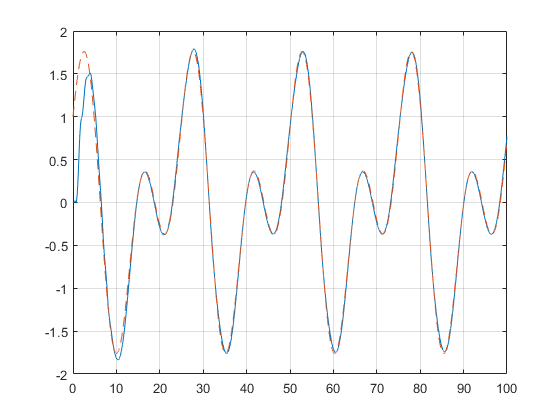

x = zeros(2, length(t));
zeta = zeros(2, length(t));
xi_hat = zeros(2, length(t));
x(:, 1) = x0;
zeta(:, 1) = zeta0;

u = zeros(length(t), 1);
e = zeros(2, length(t));
y_e = zeros(length(t), 1);
r = zeros(length(t), 1);

x_cnn = [x(1, 1) - yd(1, 1); xi_hat(2, 1) - yd(2, 1); yd(:, 1)] - [zeta(:, 1); 0; 0];
[u(1), delta_u] = control_saturation(-Wc*tanh(Vc*x_cnn), input_lower_bound, input_upper_bound);

for i = 1:length(t) - 1
    e(:, i) = [x(1, i); xi_hat(2, i)] - yd(:, i) - zeta(:, i);
    y_e(i) = C'*x(:, i) - C'*xi_hat(:, i);
    r(i) = [Lambda 1]*e(:, i);
    
    x_onn = [x(1, i); xi_hat(2, i); u(i)];
    x_cnn = [x(1, i) - yd(1, i); xi_hat(2, i) - yd(2, i); yd(:, i)] - [zeta(:, i); 0; 0];
    
    % backpropagation
    dWo = (y_e(i)*C'*inv(Aocl)*B)'*tanh(Vo*x_onn)';
    dVo = (y_e(i)*C'*inv(Aocl)*B*Wo*(eye(hidden_layer_size_onn) - diag(tanh(Vo*x_onn).^2)))'*x_onn';
    dWc = r(i)*[Lambda 1]*(Obs*inv(Ac)*ones(2, 1) - inv(K)*h*delta_u)*tanh(Vc*x_cnn)';
    dVc = r(i)*([Lambda 1]*(Obs*inv(Ac)*ones(2, 1) - inv(K)*h*delta_u)*Wc*(eye(hidden_layer_size_cnn) - diag(tanh(Vc*x_cnn).^2)))'*x_cnn';
    
    % update
    Wo = Wo + Ts*(-lr_o*dWo - gamma_o*norm(y_e(i))*Wo);
    Vo = Vo + Ts*(-lr_o*dVo - gamma_o*norm(y_e(i))*Vo);
    Wc = Wc + Ts*(-lr_c*dWc - gamma_c*norm(r(i))*Wc - gamma_c*norm(zeta(:, i))*Wc);
    Vc = Vc + Ts*(-lr_c*dVc - gamma_c*norm(r(i))*Vc - gamma_c*norm(zeta(:, i))*Vc);
    
    u(i) = -Wc*tanh(Vc*x_cnn);
    [u(i), delta_u] = control_saturation(u(i), input_lower_bound, input_upper_bound);
    
    H_hat = Wo*tanh(Vo*x_onn);
    
    x(:, i + 1) = x(:, i)+ Ts*van_der_pol_derivatiave(x(:, i), u(i), mu);
    zeta(:, i + 1) = zeta(:, i) + Ts*aux_system_derivative(zeta(:, i), delta_u, K, h);
    xi_hat(:, i + 1) = xi_hat(:, i) + Ts*observer_derivative(xi_hat(:, i), A, B, C, G, C'*x(:, i), H_hat);
end

figure, 
plot(t, x(1, :)); grid; hold on;
plot(t, yd(1, :), '--');

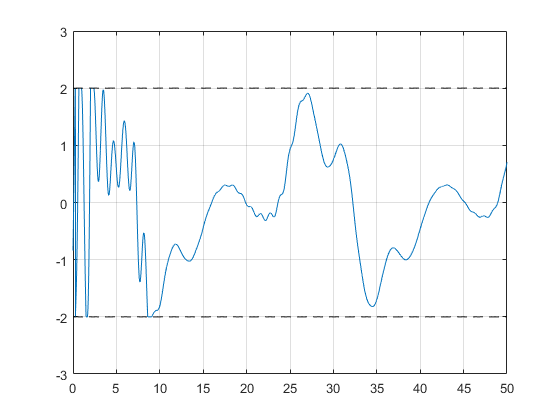


figure, 
plot(t, u); grid; hold on;
plot(t, input_lower_bound*ones(length(t), 1), "Color","Black", "LineStyle","--");
plot(t, input_upper_bound*ones(length(t), 1), "Color","Black", "LineStyle","--");
axis([0 50 input_lower_bound - 1 input_upper_bound + 1])

function [u_saturated, delta_u] = control_saturation(u, lower_bound, upper_bound)
   if u < lower_bound
       u_saturated = lower_bound;
   else 
       if u > upper_bound
           u_saturated = upper_bound;
       else
           u_saturated = u;
       end
   end
   
   delta_u = u - u_saturated;
end

function dx = van_der_pol_derivatiave(x, u, mu)
    dx = [x(2);
          mu*(1 - x(1)^2)*x(2) - x(1) + u];
end

function dzeta = aux_system_derivative(zeta, delta_u, K, h)
    dzeta = K*zeta + h*delta_u;
end

function dxi_hat = observer_derivative(xi_hat, A, B, C, G, y, H_hat)
    dxi_hat = A*xi_hat + B*H_hat + G*(y - C'*xi_hat);
end

function y = tanh(x)
    y = (exp(x) - exp(-x))./(exp(x) + exp(-x));
end